# The decoding error disaggregated across spatial-directional bins

Load the example session from Mouse2022:

n_reps = 80;

sm = SessManager;
d = sm.cons_usable(SessManager.special_sessions_usable_index_single('Mouse2022'));

Perform decoding, saving the full set of predictions:

[me_bins, me_bins_shuf] = deal(zeros(n_reps, d.opt.n_bins));
t_ = tic;
%parpool(8);
WaitMessage = parfor_wait(n_reps);
parfor j = 1:n_reps
    [~, ~, ps, ks, ~] = d.basic_decode(false,[],[]);
    [~, ~, ps_shuf, ks_shuf, ~] = d.basic_decode(true,[],[]);
    toc(t_)
    
    me_bins(j,:) = binwise_error(ks, ps, d.opt);
    me_bins_shuf(j,:) = binwise_error(ks_shuf, ps_shuf, d.opt);
    WaitMessage.Send;
end

Elapsed time is 140.686474 seconds.
Elapsed time is 140.445672 seconds.
Elapsed time is 140.341582 seconds.
Elapsed time is 141.305198 seconds.
Elapsed time is 140.600715 seconds.
Elapsed time is 143.448340 seconds.
Elapsed time is 145.914121 seconds.
Elapsed time is 154.145116 seconds.
Elapsed time is 155.818094 seconds.
Elapsed time is 155.262772 seconds.
Elapsed time is 156.857900 seconds.
Elapsed time is 159.996312 seconds.
Elapsed time is 162.321439 seconds.
Elapsed time is 163.706536 seconds.
Elapsed time is 164.209787 seconds.
Elapsed time is 166.091013 seconds.
Elapsed time is 284.088991 seconds.
Elapsed time is 283.543819 seconds.
Elapsed time is 285.142295 seconds.
Elapsed time is 294.640443 seconds.
Elapsed time is 296.144825 seconds.
Elapsed time is 296.095923 seconds.
Elapsed time is 297.394718 seconds.
Elapsed time is 298.870200 seconds.
Elapsed time is 300.273496 seconds.
Elapsed time is 301.633681 seconds.
Elapsed time is 305.653521 seconds.
Elapsed time is 306.703547 s

WaitMessage.Destroy;

Use ps (the predictions) and ks (the true bins) to find the binwise error rate:

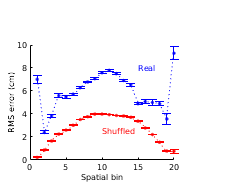

figure;
errorbar(1:d.opt.n_bins, mean(me_bins), 1.96*std(me_bins)./sqrt(n_reps), 'b.:');
hold on
errorbar(1:d.opt.n_bins, mean(me_bins_shuf), 1.96*std(me_bins_shuf)./sqrt(n_reps), 'r.:');
xlabel 'Spatial bin'
ylabel 'RMS error (cm)'

text(15, 8, 'Real', 'Color', 'b');
text(10, 2.5, 'Shuffled', 'Color', 'r');

figure_format([1.5 1.2]);
Utils.printto('supfigs_code', 'decoder_by_bins.pdf');

save decoder_by_bins.mat me_bins me_bins_shuf

Function for computing the disaggregated error across spatial bins (but still aggregated based on direction of motion)

function me_bins = binwise_error(ks, ps, opt)
ks_s = ceil(ks/2);
ps_s = ceil(ps/2);

me_bins = zeros(1, opt.n_bins);
for i = 1:opt.n_bins
    k = ks_s(ks_s == i);
    p = ps_s(ks_s == i);
    
    %me_bins(i) = mean(abs(k - p)) * opt.bin_width;
    me_bins(i) = sqrt(mean((k - p).^2)) * opt.bin_width;
end
end